clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;

% param.model.Dg*param.ctrl.Lambda_Bar

% Skriver en diagonal -1 på integralstaten.
% for i=1:4
%     param.model.A(3*i,3*i) = -1
% end

## Control

[param.ctrl.Ks, ~] = control.DesignProcedure1_paper(param,0); 

sol = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2409890 (R2023b) Update 3'
       yalmiptime: 0.0548
       solvertime: 0.0032
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


LPV
eig LPV


ans = 1.0e+03 *

   -0.0010
   -0.0010
   -0.0010
   -0.0010
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


Evaluation of design procedure 1 
cali_Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


cali_R is positive definite


ans = 1.0e-10 *

    0.0007    0.0008    0.0008    0.0008    0.0035    0.0037    0.0040    0.0042    0.1596    0.1922    0.2206    0.2283


Tau is found to be:


ans = -4.5351e-19

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7633 + 5.6104i  -0.7633 - 5.6104i  -0.4591 + 6.3840i  -0.4591 - 6.3840i  -0.3645 + 6.6218i  -0.3645 - 6.6218i  -0.3397 + 6.6635i  -0.3397 - 6.6635i  -0.2748 + 0.0000i  -0.2731 + 0.0000i  -0.2726 + 0.0000i  -0.2727 + 0.0000i


eigenvalues of A


ans =          0
         0
         0
         0
   -4.0442
   -0.0312
   -0.0311
   -4.0059
   -0.0311
   -4.0059


eigenvlaues of Bk


ans =     2.2429
    2.8461
    3.0608
    3.0902
         0
         0
         0
         0
         0
         0


res = 0

% param.ctrl.Ks = control.DesignProcedure2(param,0);

%param.ctrl.Ks = control.DesignProcedureDScalingDiag(param,0);
%param.ctrl.Ks = control.DesignProcedureFunky(param,0);
%param.ctrl.Ks = control.DesignRobust(param,0);

K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B

M =
 
  From input 1 to output...
             2.745 s^47 + 11.2 s^46 + 1367 s^45 + 1093 s^44 + 2.577e05 s^43 - 1.428e06 s^42 + 1.388e07 s^41 - 5.717e08 s^40 - 3.245e09 s^39 - 1.099e11 s^38 - 8.373e11 s^37 - 1.346e13 s^36 - 1.016e14 s^35 - 1.158e15 s^34 - 8.114e15 s^33 - 7.324e16 s^32 - 4.658e17 s^31 - 3.486e18 s^30 - 1.99e19 s^29 - 1.261e20 s^28 - 6.404e20 s^27 - 3.466e21 s^26 - 1.552e22 s^25 - 7.167e22 s^24 - 2.798e23 s^23 - 1.092e24 s^22 - 3.654e24 s^21 - 1.182e25 s^20 - 3.302e25 s^19 - 8.548e25 s^18 - 1.908e26 s^17 - 3.712e26 s^16 - 6.092e26 s^15 - 7.929e26 s^14 - 7.948e26 s^13 - 6.135e26 s^12 - 3.683e26 s^11 - 1.739e26 s^10 - 6.509e25 s^9 - 1.94e25 s^8 - 4.603e24 s^7 - 8.644e23 s^6 - 1.269e23 s^5 - 1.428e22 s^4 - 1.188e21 s^3 - 6.897e19 s^2 - 2.494e18 s - 4.231e16
   1:  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

## Structured uncertainties

s = tf('s');

w = 1;


An = [param.model.A+param.model.B*K*eye(12)];

M = K*eye(12)/(s*eye(12) - ( param.model.A + param.model.B*K*eye(12) ) )*param.model.B;
hinfnorm(M)

ans = Inf


W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0037    1.0039    1.0040    1.0042    1.0044    1.0045    1.0047    1.0049    1.0051    1.0053    1.0055    1.0058    1.0060    1.0062    1.0065    1.0067    1.0070    1.0072    1.0075    1.0078    1.0081    1.0083    1.0086    1.0090    1.0093    1.0096    1.0099    1.0103    1.0106    1.0110    1.0113    1.0117    1.0121    1.0125    1.0128    1.0132    1.0137    1.0141    1.0145    1.0149    1.0153    1.0158    1.0162    1.0167    1.0171    1.0176    1.0181    1.0185    1.0190    1.0195
    1.0028    1.0029    1.0030    1.0032    1.0033    1.0034    1.0036    1.0037    1.0039    1.0040    1.0042    1.0043    1.0045    1.0047    1.0049    1.0050    1.0052    1.0054    1.0056    1.0058    1.0060    1.0063    1.0065    1.0067    1.0069    1.0072    1.0074    1.0077    1.0079    1.0082    1.0085    1.0087    1.0090    1.0093    1.0096    1.0099    1.0102    1.0105    1.0108    1.0111    1.0114    1.0117    1.0120    1.0124    1.0127    1.0130    1.0134    1.0137    1.0141    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


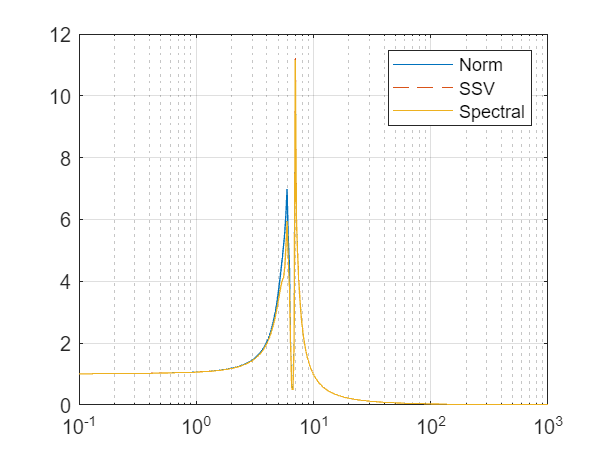


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))


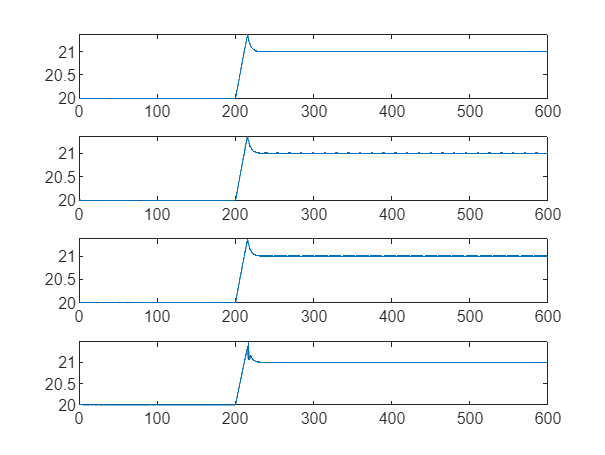

for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode45(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0,options);

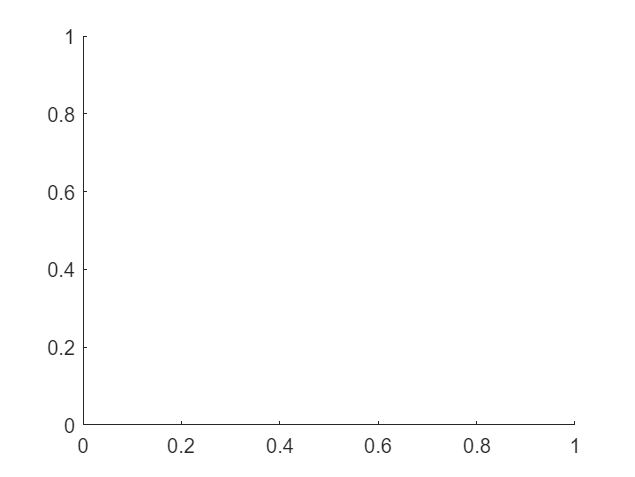

Dot indexing is not supported for variables of this type.

coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,i).Ta-273.15)
end

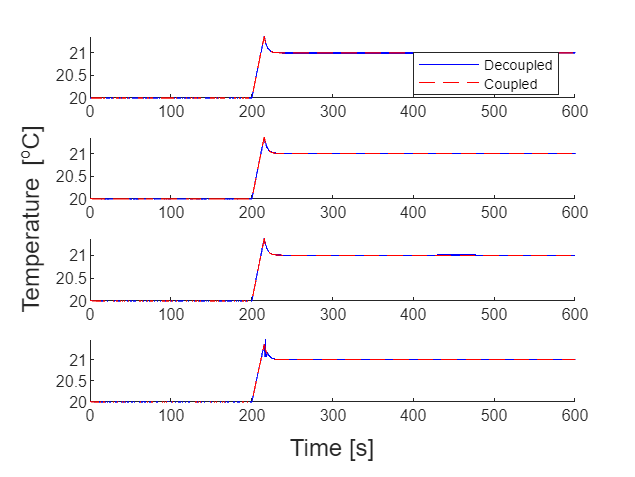

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')